# **Demo -- Optimization**

This demo shows the steps of the optimization for the project on:

"**Encoding and Switching Between Attractors and Limit Cycles Using Dynamical Systems With Bifurcations"**

clear all;
close all;

## Add dependencies and folders to path

addpath(genpath('.'));

## Load  and prepare data

You can load data from a .csv file or from a .mat file:

ld = 1;
if(ld == 1)
    [data,time] = loadData([],4,1);     % leave it empty to select file at runtime
    traj.data = data(35:5035,:);
    traj.time = time(35:5035,:);
    traj.size = size(traj.data,1);
else
    load('circle_rho2_M3_Rm1_th0_th0_th0.mat');
end

Now we prepare the data and convert it to spherical coordinates:

if (exist('Xstored','var'))
    type = 1;
    X = Xstored;
    time = [];
    smoothing = 0;
    T = 1000;
elseif (exist('trial','var'))
    type = 2;
    X = [trial.position_real.x, trial.position_real.y, trial.position_real.z];
    time = trial.position_real.time;
    smoothing = 10;
    T = [];
elseif (exist('traj','var'))
    type = 3;
    X = traj.data;
    smoothing = 0;
    time = traj.time;
    if (isfield(traj,'size'))
        T = traj.size;
    else
        T = [];
    end
end
[Xdata,Xvel,Rdata,Rvel,dt,T,N,m,begin] = prepareData(type,X,time,smoothing,T);

## Plot data

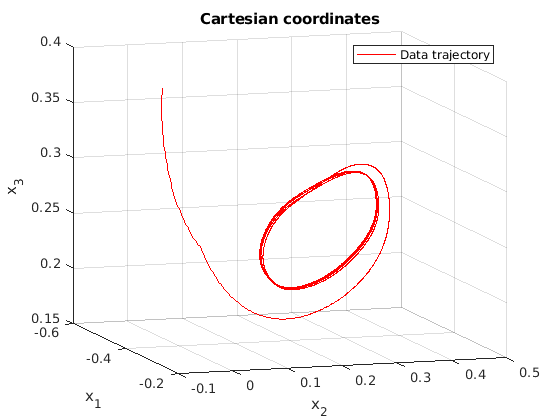

plotData(Xdata,Xvel,Rdata,Rvel,T,m,'cartp');
legend('Data trajectory','Location','northeast');

## Find $\omega$ limit set

Initialize and perform Expectation Maximization on a Gaussian Mixture Model with only 1 Gaussian to find the model of the limit set:

[Priors, Mu, Sigma] = EM_init_kmeans([Xdata';Xvel'], 1);
[Priors, Mu, Sigma] = EM([Xdata';Xvel'], Priors, Mu, Sigma);

Plot the cluster found as the $\omega$ limit set:

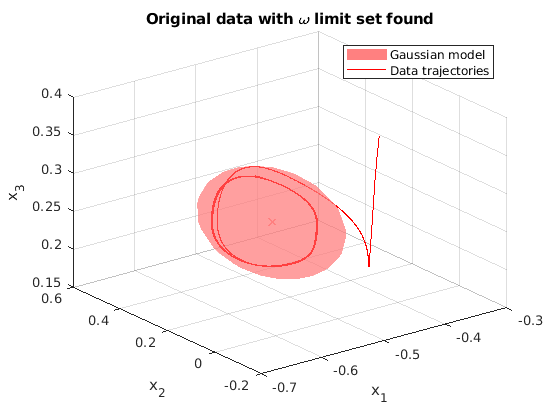

figure; grid on; hold on; view(3);
title('Original data with \omega limit set found');
xlabel('x_1'); ylabel('x_2'); zlabel('x_3');
plotGMM(Mu(1:3,:), Sigma(1:3,1:3,:), [1 0.5 0.5], 4);
plot3(Xdata(:,1), Xdata(:,2), Xdata(:,3), 'r');
legend('Gaussian model','Data trajectories','Location','northeast');

Find and plot for value of log likelihood for each point:

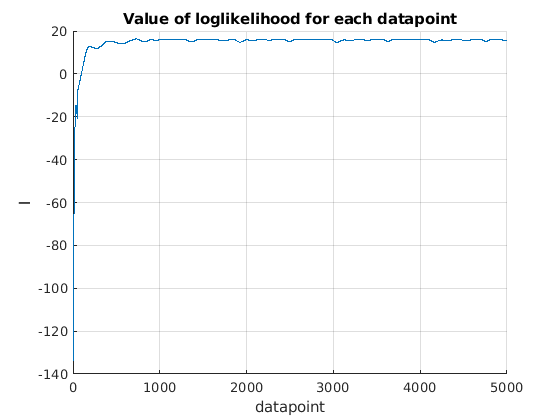

P_xi = log(gaussPDF([Xdata';Xvel'], Mu(:,1), Sigma(:,:,1)));

figure; grid on; hold on;
title('Value of loglikelihood for each datapoint');
xlabel('datapoint'); ylabel('l');
plot(P_xi);

## If wanted, perfom dimensionality reduction

Decide if you want to perform dimensionality reduction:

prompt = 'Enter 1 to perform dimensionality reduction and 0 to skip it\n';
dimred = input(prompt);

Decide the minimum threshold of log-likelihood to belong in the cluster:

if (dimred == 1)
    prompt = 'Enter cutoff threshold for log likelihood\n';
    threshold = input(prompt);
end

If wanted, perform dimensionality reduction (PCA) and plot projected data:

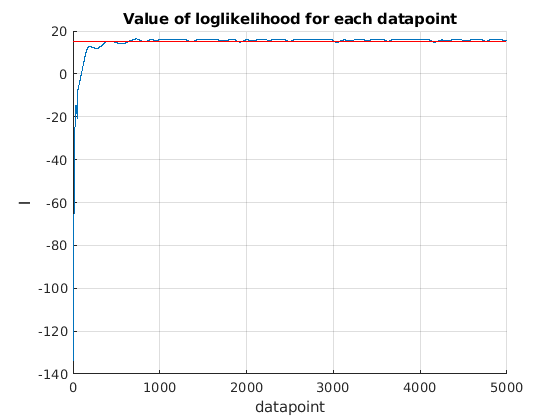

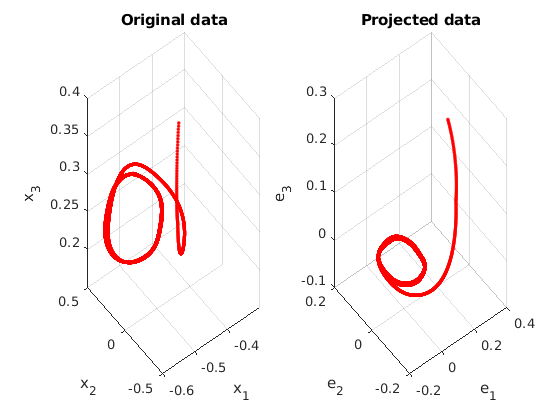

if (dimred == 1)
    % Show threshold on plot
    plot(1:T,repmat(threshold,T),'r');
    % Select points belonging to the cluster found
    ind = find(P_xi > threshold);
    XdataOmega = Xdata(ind,:);
    % Perform PCA
    opts.mean = Mu(1:N,1)';
    method = 'PCA';
    opts.plots = 0;
    [Xdatarot,Rrot] = dimreduce(XdataOmega,method,opts);
    % Get rotation matrix
    if(strcmp(method,'PCA'))
        x0_PCA = Rrot.mean;
        Rrot = Rrot.M;
    end
    
    % Plot projected (rotated) data
    figure; hold on; grid on;
    subplot(1,2,1); hold on; grid on;
    title('Original data'); xlabel('x_1'); ylabel('x_2'); zlabel('x_3');
    subplot(1,2,2); hold on; grid on;
    title('Projected data'); xlabel('e_1'); ylabel('e_2'); zlabel('e_3');
    
    for i = 1:sum(T)
        Xplot = (Rrot \ (Xdata(i,:)' - Mu(1:N,1)))';
        if N == 2
            subplot(1,2,1); plot(Xdata(i,1), Xdata(i,2), 'r.'); grid on; hold on;
            subplot(1,2,2); plot(Xplot(1), Xplot(2), 'r.'); grid on; hold on;
        else
            subplot(1,2,1); view(3); plot3(Xdata(i,1), Xdata(i,2), Xdata(i,3), 'r.'); grid on; hold on;
            subplot(1,2,2); view(3); plot3(Xplot(1), Xplot(2), Xplot(3), 'r.'); grid on; hold on;
        end
    end
else
    % If you are not performing dimensionality reduction
    Rrot = eye(N);
end


% Find Euler angle (or rotation angle if N = 2)
if(N == 3)
    theta0 = rotm2eul(Rrot)
elseif(N == 2)
    theta0 = acos(Rrot(1,1))
end

theta0 =    -1.9029    0.4024    0.3547



% Get rotated data and save original data
Xdata_ = Xdata;
Xdata = (Rrot \ (Xdata' - Mu(1:N,1)))';

## Optimization

Select initial values of paramaters and optimize:

initial_parameters = [];
initial_parameters.rho0 = 3*mean(diag(Sigma(1:N,1:N,1)));
% If you want to exclude x0 from optimization, use x0 = []
initial_parameters.x0 = [];
[params] = optimizePars(initial_parameters,Xdata,dt,begin,1);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<stopping cri

err1 = 0.6373

err2 = 30.3717

Parameters found by optimization:


params = struct with fields:
    rho0: 0.1002
       M: 0.5235
       R: -0.5637
       a: [1 1.1434 1]
      x0: [0 0 0]


## Get parameters learned

rho0 = params.rho0;
M = params.M;
R = params.R;
% Rewrite a to include rotation matrix
a = Rrot; for i = 1:N; a(i,i) = a(i,i) / params.a(i); end
% Add the mean of the Gaussian model to x0
if isfield(initial_parameters,'x0') && isempty(initial_parameters.x0)
    x0 = -Mu(1:N,1)';
else
    x0 = (Rrot * params.x0' - Mu(1:N,1))';
end
params.x0 = x0;
params.theta0 = theta0;
disp(params);

      rho0: 0.1002
         M: 0.5235
         R: -0.5637
         a: [1 1.1434 1]
        x0: [0.4929 -0.2973 -0.2331]
    theta0: [-1.9029 0.4024 0.3547]



## Functions to plot learned dynamics

dU = @(r,M,rho0,R) 2.*M.*(r(:,1) - rho0);
dRho = @(r,M,rho0,R) - sqrt(M.*2) .* (r - rho0);
dTheta = @(r,M,rho0,R) R .* exp(-dU(r(:,1),M,rho0,R).^2);

r = @(Xplot) cart2hyper((a\(Xplot+x0)')');
if N == 3
    dr = @(r) [dRho(r(:,1),M,rho0,R), dRho(r(:,2),M,0,R), dTheta(r(:,1),M,rho0,R)];
else
    dr = @(r) [dRho(r(:,1),M,rho0,R), dTheta(r(:,1),M,rho0,R)];
end
y = @(Xplot) sph2cartvelocities(r(Xplot),dr(r(Xplot))); % dynamics to be plotted

## Plot learned dynamics with original data and new trajectories

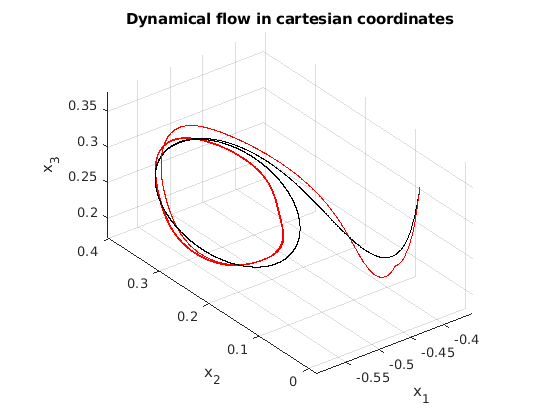

% Get unrotated data
Xdata = Xdata_;

% Plot original data
figure; title('Dynamical flow in cartesian coordinates'); hold on; grid on;
if N == 2
    plot(Xdata(:,1),Xdata(:,2),'r.'); hold on;
else
    view(3);
    plot3(Xdata(1:T(1),1),Xdata(1:T(1),2),Xdata(1:T(1),3),'r'); hold on;
    for i = 2:m
        plot3(Xdata(sum(T(1:i-1))+1:sum(T(1:i)),1),...
            Xdata(sum(T(1:i-1))+1:sum(T(1:i)),2),...
            Xdata(sum(T(1:i-1))+1:sum(T(1:i)),3),'r'); hold on;
    end
end

% Plot streamlines / arrows to show dynamics
%axis equal;
ylabel('x_2'); yl = ylim;
xlabel('x_1'); xl = xlim;
if N > 2
    zlabel('x_3'); zl = zlim;
    ngrid = 7;
end

if N == 2
    [Xs,Ys] = meshgrid(linspace(xl(1),xl(2),20),linspace(yl(1),yl(2),20));
    X_plot = [Xs(:), Ys(:)];
else
    [Xs,Ys,Zs] = meshgrid(linspace(xl(1),xl(2),ngrid),...
        linspace(yl(1),yl(2),ngrid),linspace(zl(1),zl(2),ngrid));
    X_plot = [Xs(:), Ys(:), Zs(:)];
end
Y = zeros(size(X_plot));
for i= 1:size(X_plot,1)
    Y(i,1:N) = y(X_plot(i,1:N));
end

if N == 2
    streamslice(Xs,Ys,reshape(Y(:,1),20,20),...
        reshape(Y(:,2),20,20),'method','cubic');
else
    quiver3(X_plot(:,1),X_plot(:,2),X_plot(:,3),Y(:,1),Y(:,2),Y(:,3),'color','black');
end

% Test dynamics for T time steps
X0 = Xdata(1,:);%[(a\(x0+1)')'];
Xvel_DS = []; Rad_s = []; X_s = [];
for j = 1:size(X0,1)
    X = X0(j,:);
    for i = 1:T(1)
        Rad = r(X) + dr(r(X)) * dt;
        Rad_s = [Rad_s; Rad];
        X = (a*hyper2cart(Rad)')' - x0;
        X_s = [X_s; X];
        Xvel_DS = [Xvel_DS; sph2cartvelocities(r(X),dr(r(X)))];
        if N == 2
            plot(X(1),X(2),'k.'); hold on; grid on;
        else
            plot3(X(1),X(2),X(3),'k.'); hold on; grid on;
        end
    end
end

## Interactive plot (2D)

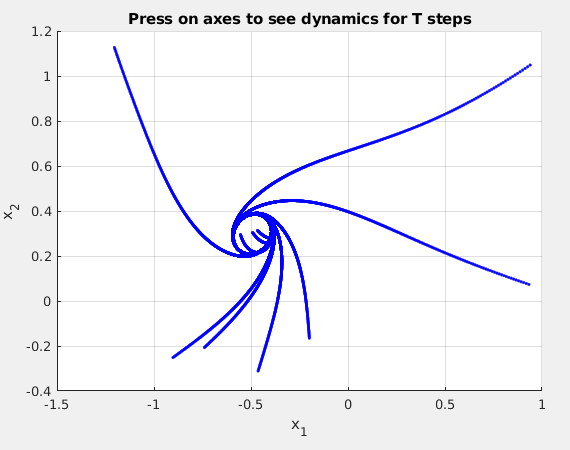

f = figure;
ax = axes('Parent',f,'position',[0.1 0.13  0.85 0.8]);
grid on; zoom on;
title('Press on axes to see dynamics for T steps');
xlabel('x_1');
ylabel('x_2');

% Read mouse clicks until a mouse right-button occurs
button = 1;
while sum(button) <=1
    [x1,x2,button] = ginput(1);
    if button == 1
        hold on; plot(x1,x2,'b.');
        X = [x1,x2];
        if N > 2
            X = [X,zeros(1,N-2)];
        end
        for i = 1:T
            Rad = r(X) + dr(r(X)) * dt;
            X = (a*hyper2cart(Rad)')' - x0;
            plot(X(1),X(2),'b.');
        end
    end
end

## Export parameters to ROS configuration file

%saveToCfg(params);